# Rotary Inverted Pendulum System Identification via Constrained Non Linear Optimization and Simulation Error Criterion

The main advantage of employing a simulation error method for system identification is that the procedure is less influenced by fast sampling times and large measurement noise.

## Unconstrained System identification via S.E.M.

startUp % load datasheet model parameter values
addpath("../Model/"); % NL equations
addpath("../optimization/UncOpt/"); % optimization routines
addpath("../optimization/ConsOpt/");
addpath("../Manual_Validation/esp/theta_esp/"); % experimental data
addpath("../Manual_Validation/esp/alpha_esp/");
addpath("../Manual_Validation/esp/theta_d_esp/");
addpath("../Manual_Validation/esp/alpha_d_esp/");
addpath("../Manual_Validation/esp/t_esp/");
addpath("../Manual_Validation/esp/voltage_esp/");

### Load the Data

Also need to add a procedure to save the results consistently and link the identification esults to the experiment used to perform identification.

Remark: for consistency of use of the optimization toolboxes we will denote in the following the state as $z$ and the decision variables as $x$.

train_exp = 32;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(train_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(train_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(train_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(train_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(train_exp)+'.mat')));
alpha_dot=cell2mat(struct2cell(load('alpha_d_esp'+ string(train_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot];

% check if voltage was measured before or after -1 gain
if uin(1,2) > 0 && theta(1,2) <= 0 || uin(1,2) < 0 && theta(1,2) >= 0
    uin = - cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % consider negative voltages
end

downsample_factor = 1;
Ts = 0.002*downsample_factor; % sampling time of the simulation/data acquisition process
z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions

### Weighting matrices for cost function and scaling factor

We should check the orders of magnitude of measured variables in order to avoid numerical issues, it would be great to normalize through a scaling factor.

% Q = eye(2);
Q = eye(4);
scaling =ones(10,1); %[1e-3 1e-3 1e-3 1e-3 1e-1 1 1e-1 1e-1 1e-3 1e-3]'; % needed only if the parameters to identify are of differnet
% orders of magnitude

### Initialize parameter estimates

we want to estimate the following physical parameters: 


$$B_p ,B_r ,J_{a\;} ,J_p ,l_p ,R_m ,\eta_g ,\eta_m ,k_m ,k_t$$


in a future version we could add the positions of the centers of mass: $l_p$

% x0 = rand([10,1]);
load("x0_BFGS.mat")

### Optimization routine

%% BFGS
% Initialize solver options
myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-9;
myoptions.ls_tkmax      =	1;          
myoptions.ls_beta       =	0.5;
myoptions.ls_c          =	1e-4;
myoptions.ls_nitermax   =	100;

% Run solver
[xstar,fxstar,niter,exitflag] = myfminunc(@(x)Rot_pend_sim_cost(x,z0,uin,ymeas,th,Ts,Q,scaling),x0,myoptions);

Iteration       NormGrad          Cost      Rel. cost         Rel. x      Line-search
        0    2.14686e+04   3.99564e+00    1.00000e+00    1.00000e+00                0
        1    1.89564e+07   3.49209e+00    1.26026e-01    5.85432e-02               17
        2    9.55738e+08   3.05965e+00    1.23834e-01    1.07864e-02               26
        3    3.34940e+02   2.85950e+00    6.54157e-02    7.57016e-03               31
        4    3.33755e+02   2.82601e+00    1.17145e-02    1.17113e-01               13
        5    3.31566e+01   2.81931e+00    2.37073e-03    8.30550e-02               14
        6    1.85946e+04   2.78417e+00    1.24632e-02    1.62046e-01               11
        7    3.87257e+02   2.76640e+00    6.38014e-03    4.42739e-02               20
        8    3.75470e+01   2.73269e+00    1.21872e-02    1.70309e-01               13
        9    8.28736e+01   2.71656e+00    5.90313e-03    1.48517e-01               11
       10    3.46272e+05   2.64422e+00    2.66285e-02 

       16    8.26695e+09   1.40323e+00    3.25852e-02    2.38971e-02               16
       17    2.92411e+01   1.37789e+00    1.80592e-02    1.52629e-02               38
       18    1.17397e+01   1.37398e+00    2.84088e-03    1.52047e-01                7
       19    8.62281e-01   1.13680e+00    1.72616e-01    1.21385e-01                5
       20    1.83997e+00   1.10992e+00    2.36450e-02    1.47273e-01                2
       21    2.30008e+00   1.09561e+00    1.28934e-02    1.36137e-02                5
       22    1.19705e+01   1.02447e+00    6.49374e-02    8.45895e-03                5
       23    1.72480e+00   9.80829e-01    4.25970e-02    1.07569e-02                8
       24    1.92978e-01   8.47649e-01    1.35782e-01    3.14651e-02                3
       25    1.84914e-01   7.99135e-01    5.72343e-02    7.88033e-02                1
       26    1.68966e-01   7.07448e-01    1.14733e-01    1.09075e-01                0
       27    1.54012e-01   6.64948e-01    6.00745e-02 


% Results
[xstar./scaling [B_p;B_r;J_a;J_p;l_p;R_m;eta_g;eta_m;k_m;k_t]]

ans =    -0.0078    0.0024
    0.9801    0.0024
    0.0849    0.0020
   -0.2490    0.0012
    1.5174    0.1560
    0.0585    2.6000
    0.0438    0.9000
    0.0315    0.6900
    0.0073    0.0077
    0.8024    0.0077


Here we plot the trajectory of the system for the optimum point and we compare it to the true behaviour of the system in both the training and the validation sets.

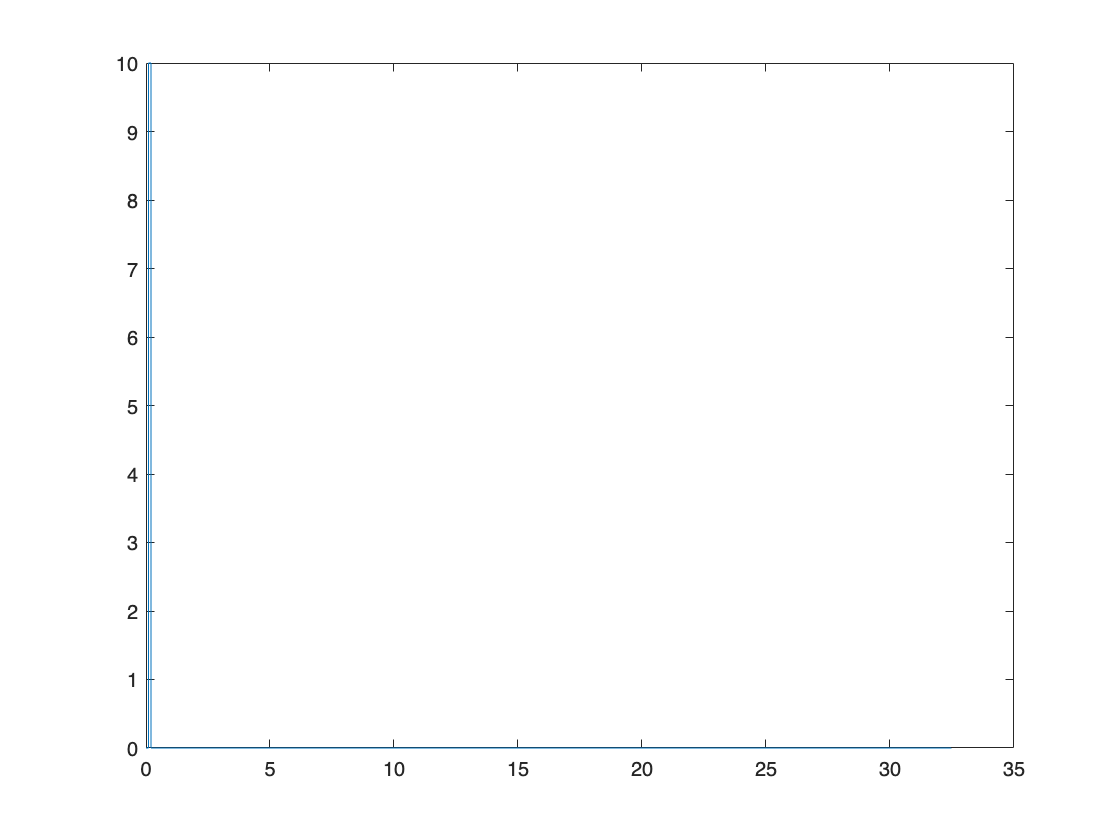

[~,ysim] = Rot_pend_sim_cost(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,uin);

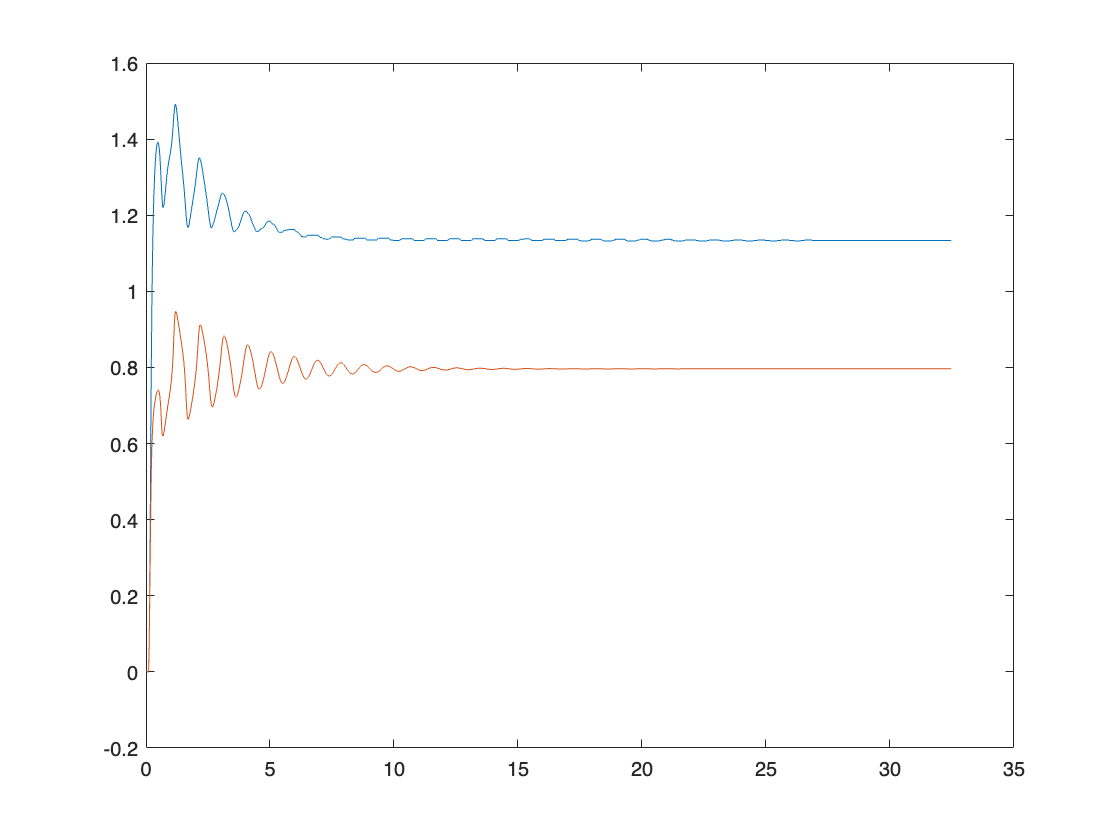

figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:))

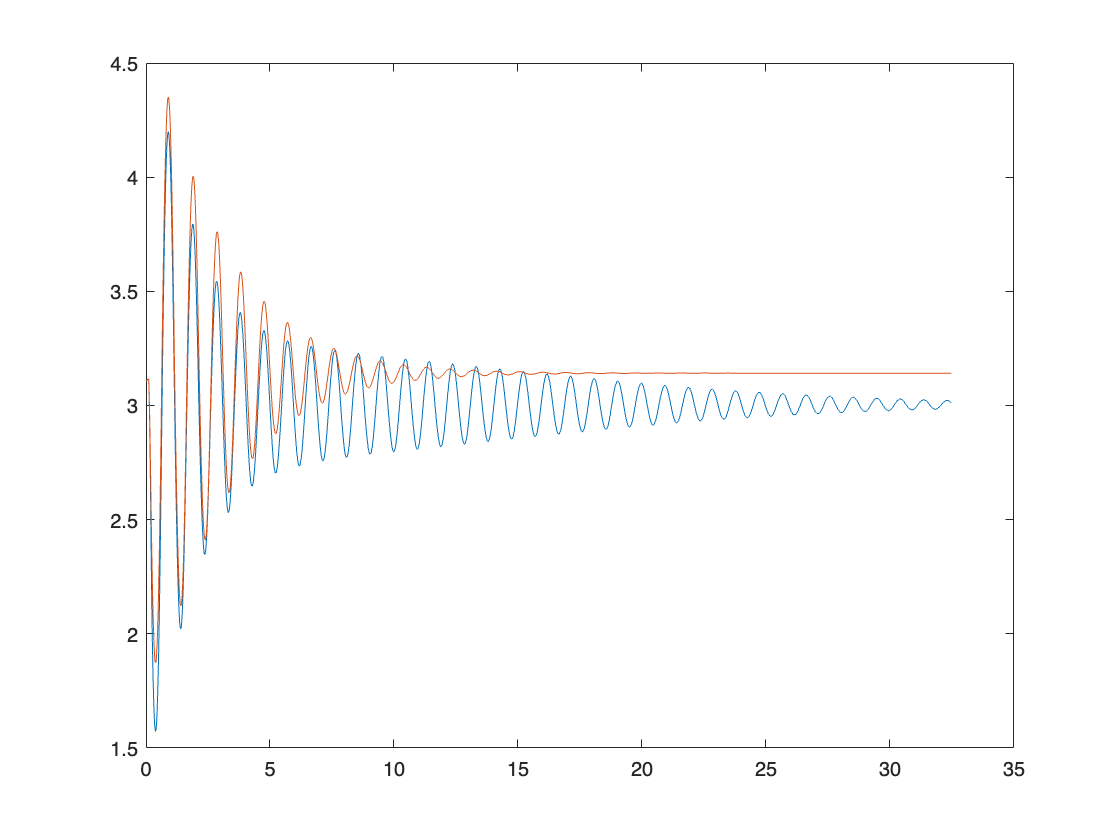

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:))

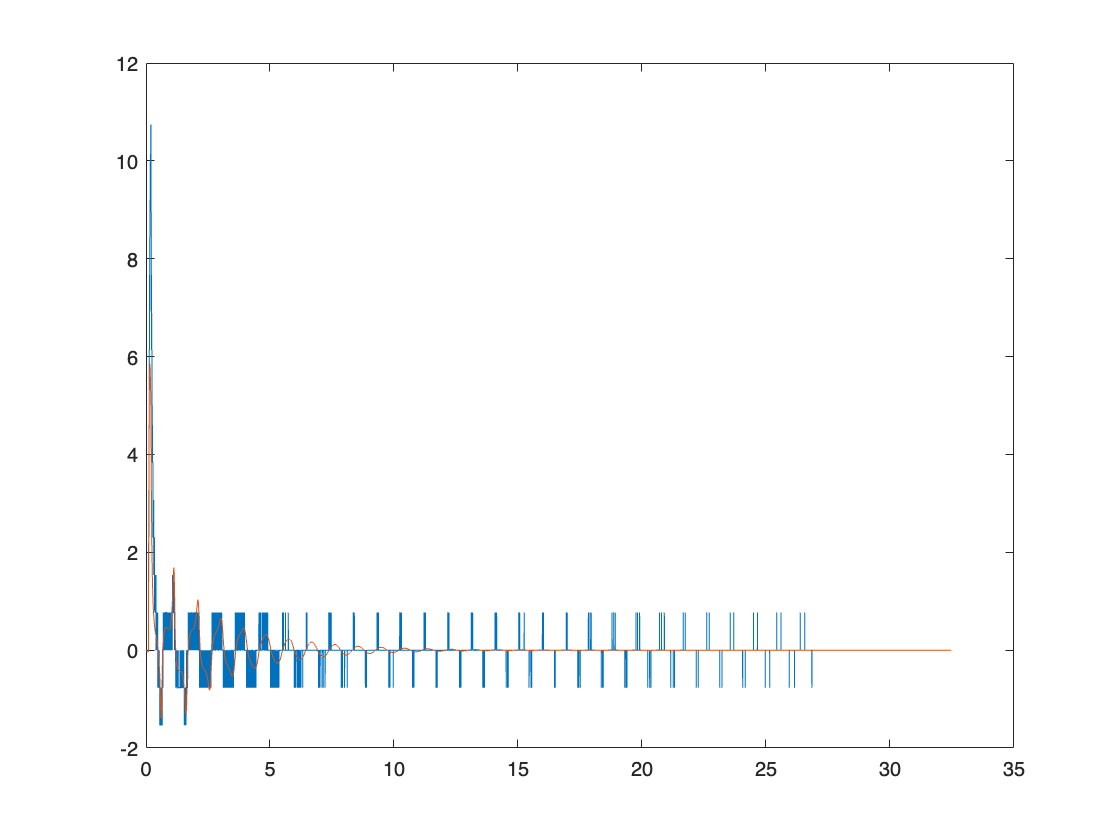

figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))

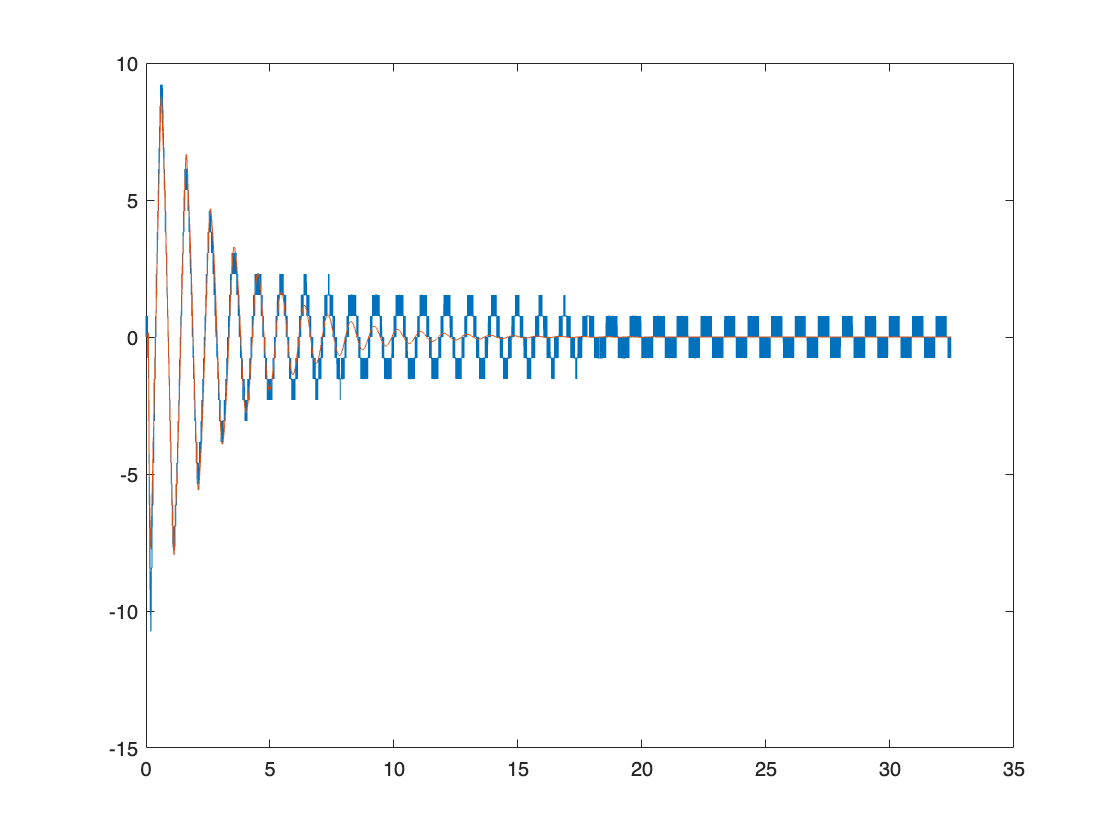

figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))

## Constrained Optimization

The unconstrained optimization above, despite giving good results leverages negative numbers which are unfeasible for physical quantities such as moment of inertia.

In the following we will try to introduce some constraints on parameter values.

### Define the linear inequality constraints matrices 

From physics we impose some limit values for the physical parameters of the system, these limits are here formulated as **linear inequality constraints**.

C = zeros(12,6);
C(1,1) = 1;
C(2,1) = -1;
C(3,2) = 1;
C(4,2) = -1;
C(5,3) = 1;
C(6,3) = -1;
C(7,4) = 1;
C(8,4) = -1;
C(9,5) = 1;
C(10,5) = -1;
C(11,6) = 1;
C(12,6) = -1;
C(13,7) = 1;
C(14,7) = -1;
C(15,8) = 1;
C(16,8) = -1;
C(17,9) = 1;
C(18,9) = -1;
C(19,10) = 1;
C(20,10) = -1;

d = [0; -0.05; 0; -0.05; 0; -0.05; 0; -0.05;0;-0.337;R_m-(R_m*0.12);-(R_m+(R_m*0.12));eta_g-(eta_g*0.1);-(eta_g+(eta_g*0.1));eta_m-(eta_m*0.1);-(eta_m+(eta_m*0.1));k_m-(k_m*0.12);-(k_m+(k_m*0.12));k_t-(k_t*0.12);-(k_t+(k_t*0.12))];

### Optimization routine

% Initialize solver options
myoptions               =   myoptimset;
myoptions.Hessmethod  	=	'BFGS';
myoptions.gradmethod  	=	'CD';
myoptions.graddx        =	2^-17;
myoptions.tolgrad    	=	1e-8;
myoptions.ls_tkmax      =	1;          
myoptions.ls_beta       =	0.5;
myoptions.ls_c          =	0.1;
myoptions.ls_nitermax   =	1e2;
myoptions.nitermax      =	1e3;
myoptions.xsequence     =	'on';

% Run solver
[xstar,fxstar,niter,exitflag,xsequence] = myfmincon(@(x)Rot_pend_sim_cost(x,z0,uin,ymeas,th,Ts,Q,scaling),x0,[],[],C,d,0,0,myoptions);

Iteration       NormGrad          Cost      Equality     Inequality     Rel. cost         Rel. x     Line-search
        0    1.46522e+00   3.99564e+00   0.00000e+00   -1.91908e+00   1.00000e+00    1.00000e+00               0
        1    5.54019e+02   3.61482e+00   0.00000e+00    2.21784e-15   9.66842e-02    1.56574e+00               0
        2    2.25988e+02   2.33329e+00   0.00000e+00    2.38038e-12   3.54522e-01    1.07827e-01               1
        3    1.14036e+02   2.25747e+00   0.00000e+00    1.78529e-12   3.24952e-02    4.15133e-02               2
        4    1.14010e+02   1.65804e+00   0.00000e+00    8.92735e-13   2.65532e-01    4.75586e-02               1
        5    1.72736e+02   1.59205e+00   0.00000e+00    2.59200e-04   3.98000e-02    1.27016e-02               2
        6    1.83233e+02   1.55815e+00   0.00000e+00    1.29604e-04   2.12907e-02    1.00027e-01               1
        7    1.52893e+02   1.53400e+00   0.00000e+00    1.83154e-04   1.55014e-02    4.91123e-03

% Results
[xstar./scaling [B_p;B_r;J_a;J_p;l_p;R_m;eta_g;eta_m;k_m;k_t]]

ans =     0.0000    0.0024
    0.0419    0.0024
    0.0020    0.0020
    0.0016    0.0012
    0.1092    0.1560
    2.2880    2.6000
    0.9900    0.9000
    0.7590    0.6900
    0.0076    0.0077
    0.0086    0.0077


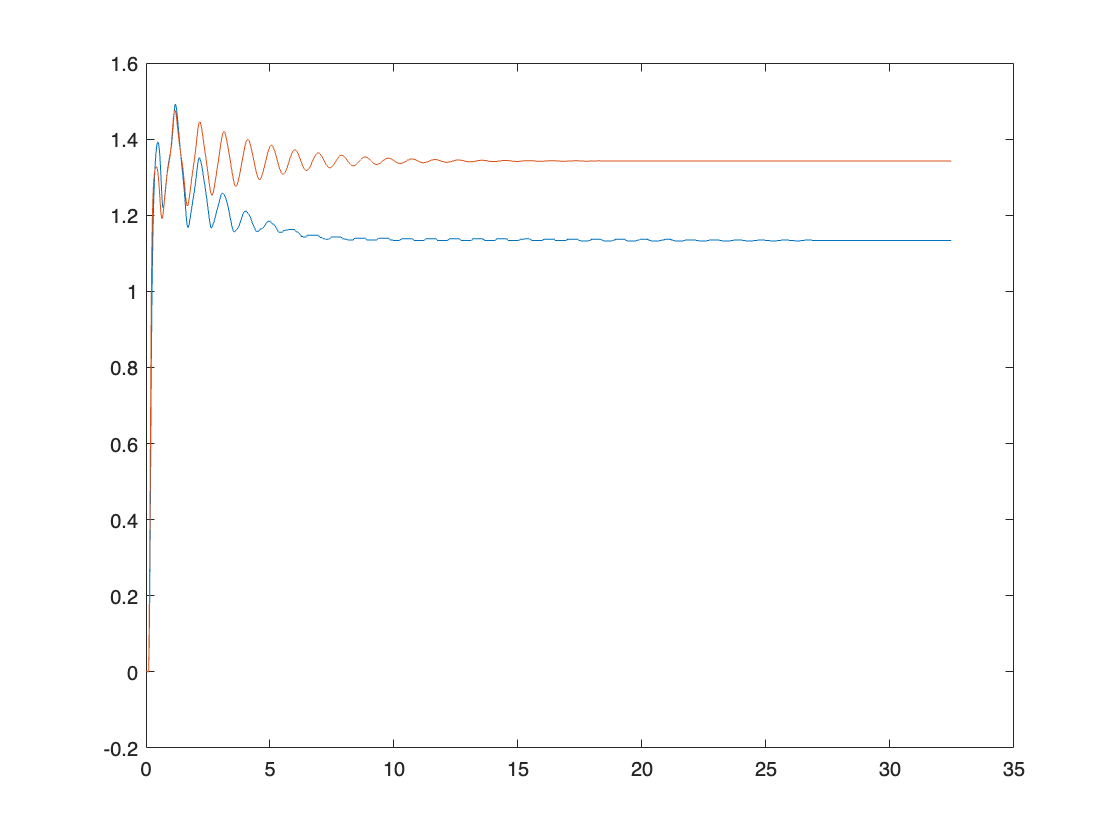

[~,ysim] = Rot_pend_sim_cost(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:))

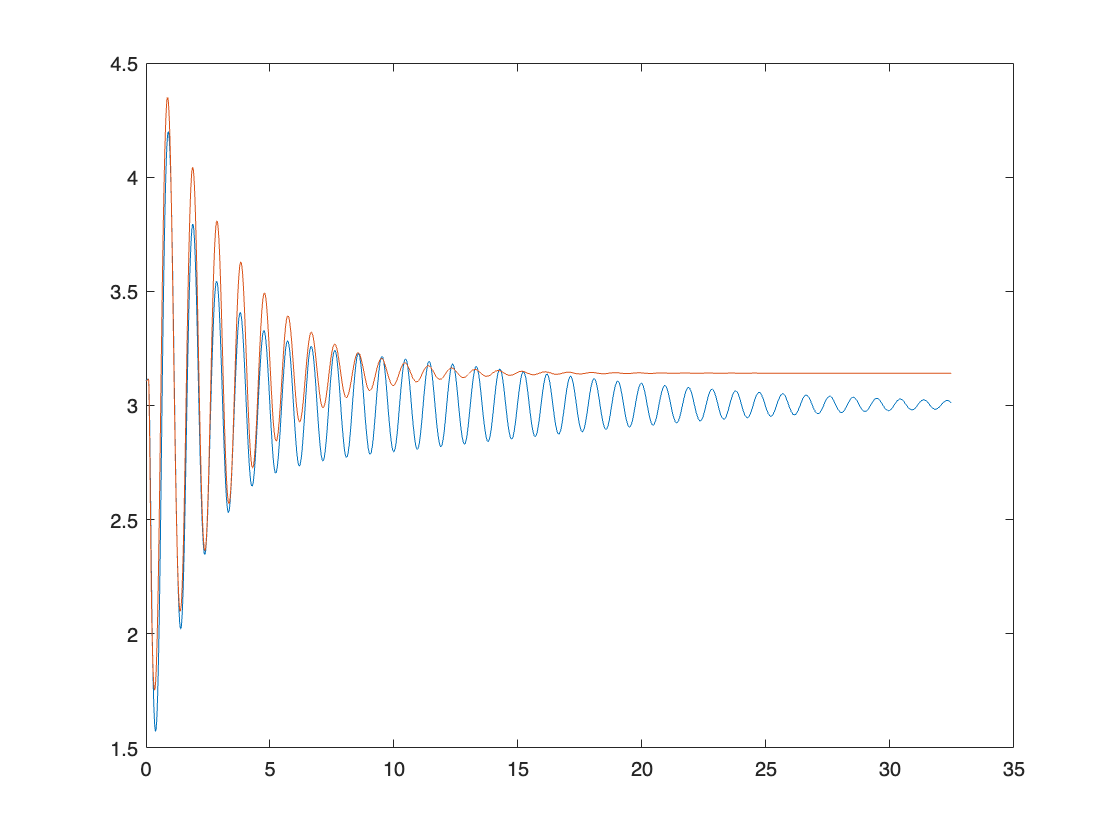

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:))

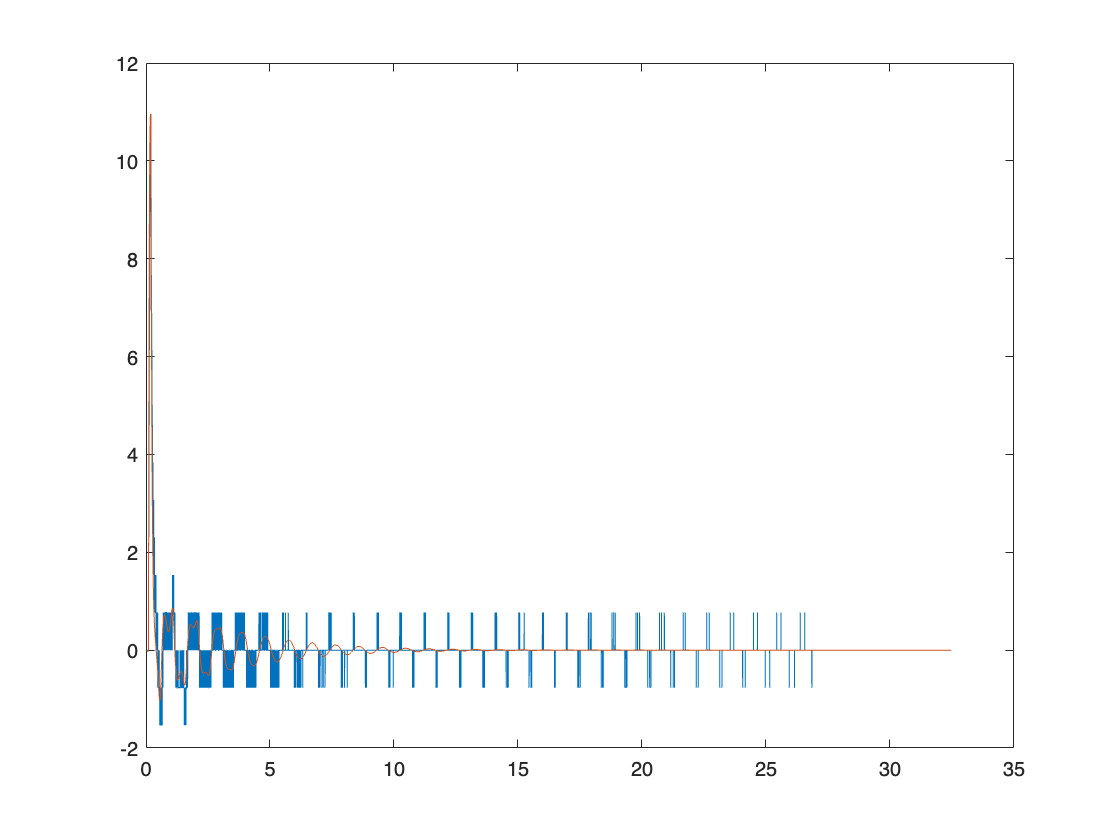

figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))

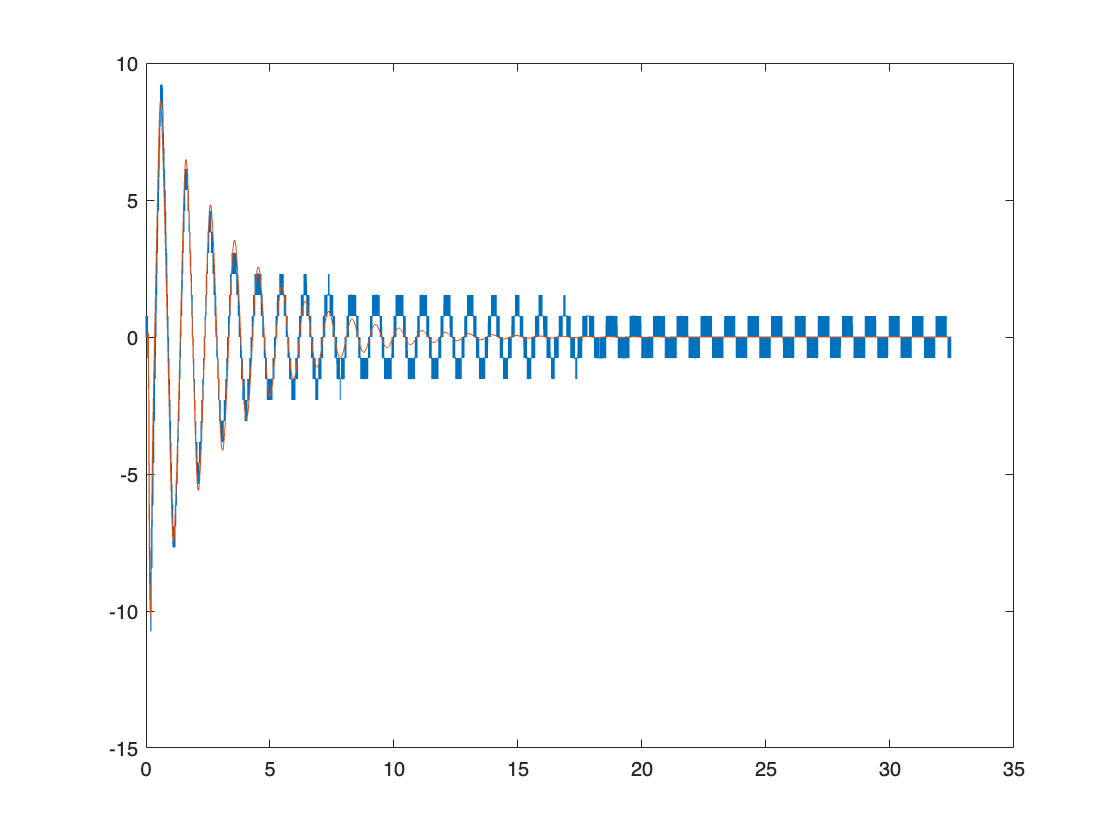

figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))

## Validation

Here we perform the validation of the identified parameters by looking at the behaviour of the non linear model against a different sineswept.

Validation with respect to the impulse response

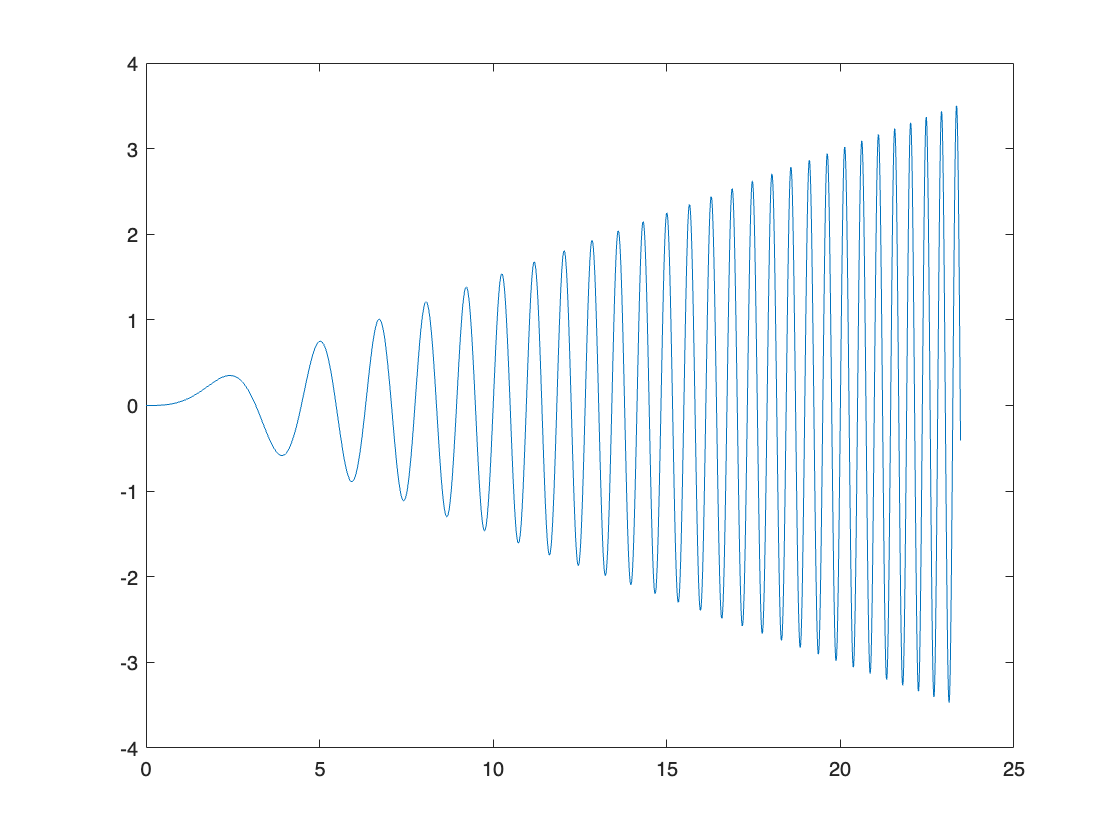

val_exp = 27;

% want row vectors !!!
uin = cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % input voltages signal collected from measurement % place negative sign
Time_vec = cell2mat(struct2cell(load('t_esp'+ string(val_exp)+'.mat'))); % time vector of the measure signals
N = length(Time_vec); % number of samples of the measurement

theta = cell2mat(struct2cell(load('theta_esp'+ string(val_exp)+'.mat')));
alpha = cell2mat(struct2cell(load('alpha_esp'+ string(val_exp)+'.mat')));
theta_dot = cell2mat(struct2cell(load('theta_d_esp'+ string(val_exp)+'.mat')));
alpha_dot = cell2mat(struct2cell(load('alpha_d_esp'+ string(val_exp)+'.mat')));

ymeas = [theta;alpha;theta_dot;alpha_dot];
z0 = [ymeas(1,1); ymeas(2,1); 0; 0]; % initial conditions given the modeling conventions

% check if voltage was measured before or after -1 gain
if uin(1,2) > 0 && theta(1,2) <= 0 || uin(1,2) < 0 && theta(1,2) >= 0
    uin = - cell2mat(struct2cell(load('voltage_esp'+ string(val_exp)+'.mat'))); % consider negative voltages
end

% simulation of the non linear system
[~,ysim] = Rot_pend_sim_err(xstar,z0,uin,ymeas,th,Ts,Q,scaling);
figure,plot(Time_vec,uin);

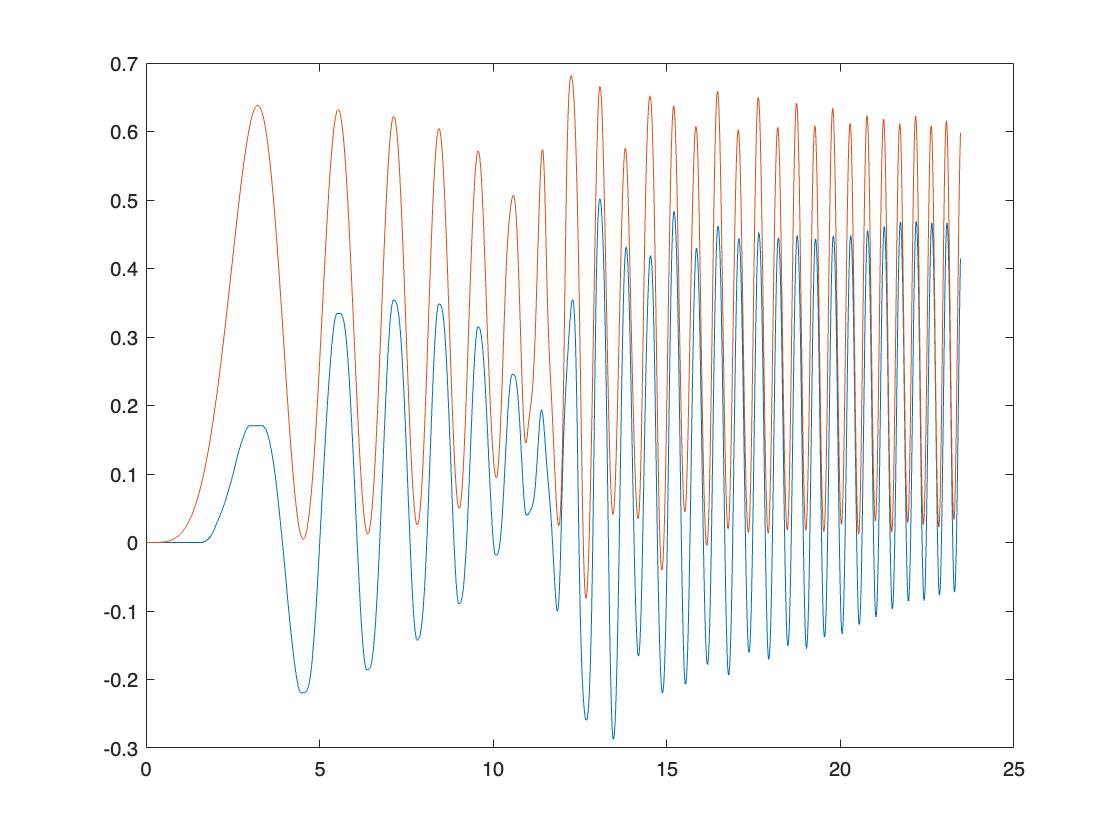

figure,plot(Time_vec,ymeas(1,:),Time_vec,ysim(1,:))

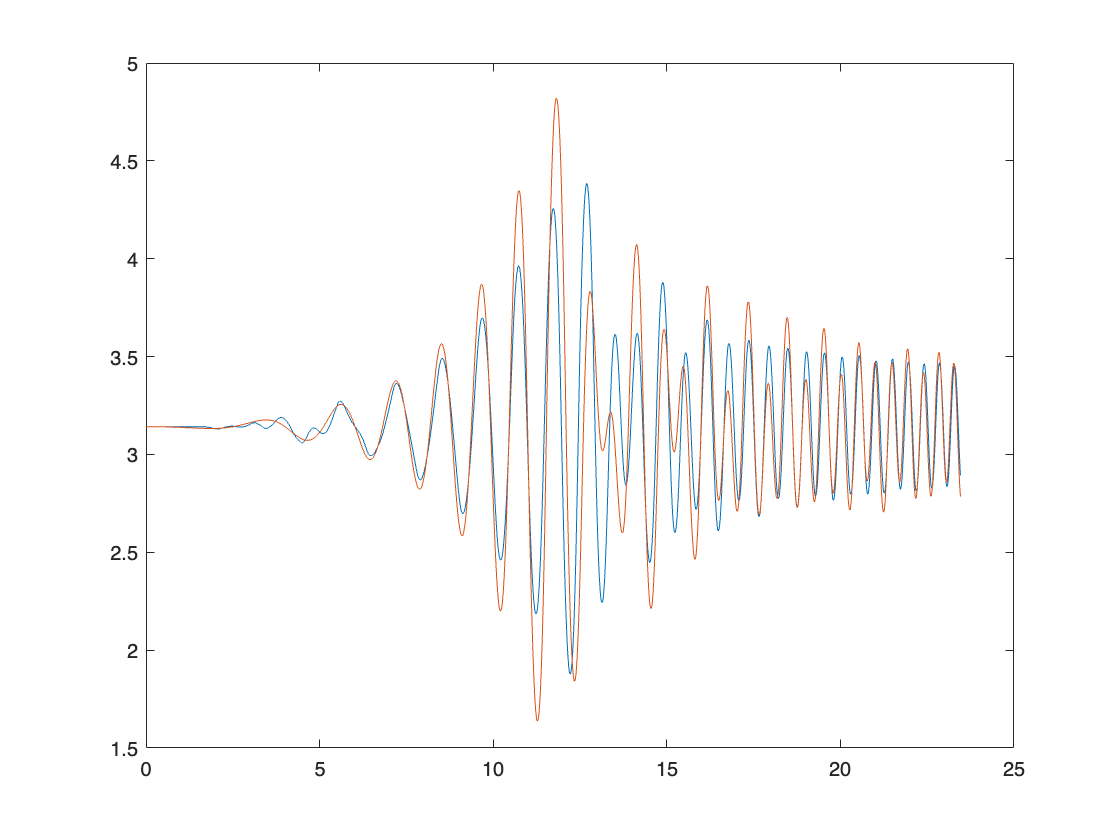

figure,plot(Time_vec,ymeas(2,:),Time_vec,ysim(2,:))

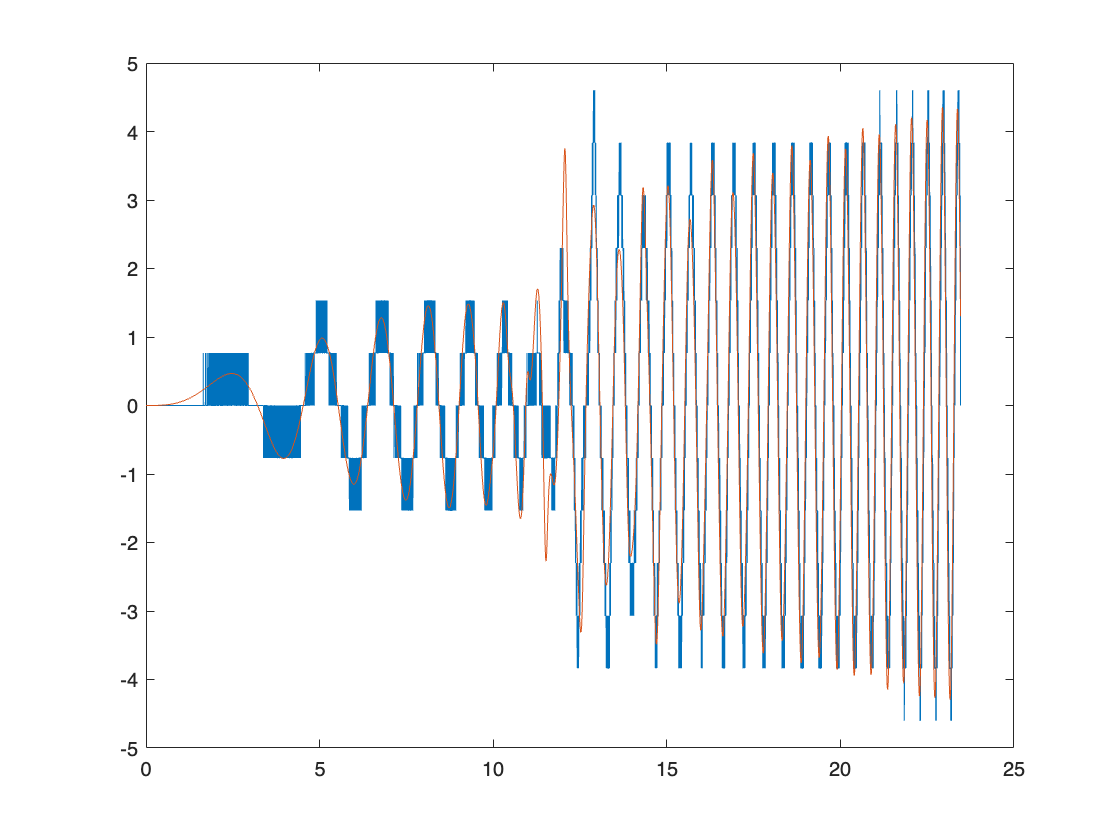

figure,plot(Time_vec,ymeas(3,:),Time_vec,ysim(3,:))

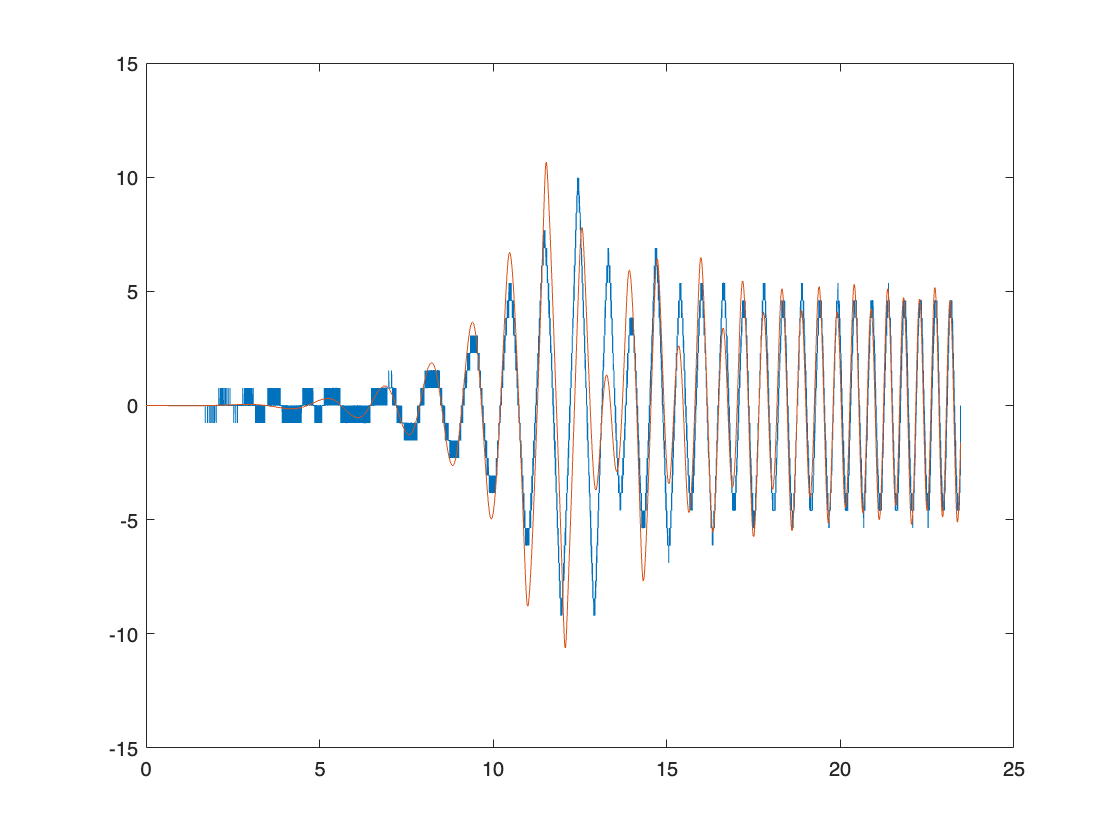

figure,plot(Time_vec,ymeas(4,:),Time_vec,ysim(4,:))